clear; clc;

% MATLAB에서 MAT 파일 로드 (연속 데이터)
data = load('0317_22epochedEEG.mat');
epochedEEG = data.epochedEEG;
continuousEEG = cell2mat(epochedEEG');

% 기본 파라미터 설정
fs = 125; % 샘플링 주파수 (Hz)
[num_samples, num_channels] = size(continuousEEG); % 연속 EEG 데이터 크기 확인

% 밴드패스 필터 생성 (1~50Hz)
[b, a] = butter(4, [1 40] / (fs/2), 'bandpass');

% 필터 적용 (각 채널별 필터링)
filteredEEG = filtfilt(b, a, continuousEEG);

disp('밴드패스 필터링 완료');

밴드패스 필터링 완료


% 공통 평균 참조(CAR) 적용
mean_signal = mean(filteredEEG, 2); % 각 샘플에서 평균 계산
CAR_EEG = filteredEEG - mean_signal; % 평균 신호 제거

disp('CAR 변환 완료');

CAR 변환 완료


% EEGLAB 구조 생성
EEG = eeg_emptyset(); 
EEG.data = CAR_EEG'; % (채널 x 샘플 형태)
EEG.srate = fs; % 샘플링 주파수 설정
EEG.nbchan = num_channels; % 채널 개수
EEG.trials = 1; % 연속 데이터이므로 trial=1
EEG.pnts = num_samples; % 샘플 개수
EEG.xmin = 0; % 시작 시간 (초)
EEG.xmax = (EEG.pnts - 1) / fs; % 종료 시간 (초)

% 채널 위치 파일 불러오기
chanlocs = readlocs('D:\W00Y0NG\PRGM2\MATLAB\eeglab2024.2\sample_locs\Standard-10-20-Cap81.ced', 'filetype', 'chanedit');

Reading file (lines): 10 20 30 40 50 60 70 80 81
readlocs() warning: Fewer columns in the input than expected.
                    See >> help readlocs



% EEG에서 사용할 16개 채널
selected_labels = {'FP1', 'FP2', 'C3', 'C4', 'P7', 'P8', 'O1', 'O2', ...
                   'F7', 'F8', 'F3', 'F4', 'T7', 'T8', 'P3', 'P4'};

% 81개 채널 중에서 16개만 선택
[~, idx] = ismember(selected_labels, {chanlocs.labels});
chanlocs_16 = chanlocs(idx(idx>0));

% EEG에 필터링된 채널 적용
EEG.chanlocs = chanlocs_16;
EEG = eeg_checkset(EEG);

% 적용된 채널 확인
disp(['적용된 채널 개수: ', num2str(length(EEG.chanlocs))]);

적용된 채널 개수: 16


disp({EEG.chanlocs.labels});

    {'FP1'}    {'FP2'}    {'C3'}    {'C4'}    {'P7'}    {'P8'}    {'O1'}    {'O2'}    {'F7'}    {'F8'}    {'F3'}    {'F4'}    {'T7'}    {'T8'}    {'P3'}    {'P4'}



EEG = pop_runica(EEG, 'extended', 1);


Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (15) is smaller than the number of channels (16).

Input data size [15,51250] = 15 channels, 51250 frames/nAfter PCA dimension reduction,
  finding 15 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 227 frames per ICA weight ((225)^2 = 51250 weights, Initial learning rate will be 0.001, block size 55.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -5076.02 to 3270.04
Reducing the data to 15 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...


step 1 - lrate 0.001000, wchange 11.16620555, angledelta  0.0 deg
step 2 - lrate 0.001000, wchange 1.58586192, angledelta  0.0 deg
step 3 - lrate 0.001000, wchange 2.90390724, angledelta 81.0 deg
step 4 - lrate 0.000980, wchange 1.50108780, angledelta 122.1 deg
step 5 - lrate 0.000960, wchange 1.29258224, angledelta 121.6 deg
step 6 - lrate 0.000941, wchange 1.02015452, angledelta 110.2 deg
step 7 - lrate 0.000922, wchange 1.66639641, angledelta 104.7 deg
step 8 - lrate 0.000904, wchange 1.66754061, angledelta 129.6 deg
step 9 - lrate 0.000886, wchange 2.14533993, angledelta 120.0 deg
step 10 - lrate 0.000868, wchange 1.70220771, angledelta 114.7 deg
step 11 - lrate 0.000851, wchange 1.70372339, angledelta 123.9 deg
step 12 - lrate 0.000834, wchange 2.16947797, angledelta 109.3 deg
step 13 - lrate 0.000817, wchange 1.74636839, angledelta 119.8 deg
step 14 - lrate 0.000801, wchange 1.55800706, angledelta 124.8 deg
step 15 - lrate 0.000785, wchange 1.65503802, angledelta 96.6 deg
step 16

Drawing figure...


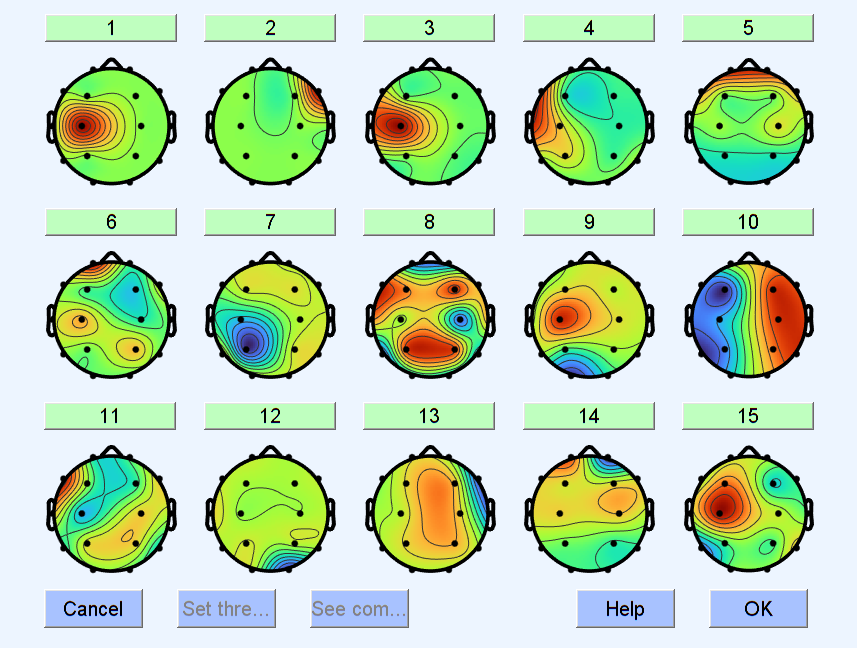

pop_selectcomps(EEG, 1:size(EEG.icawinv, 2));